# **Inspection Performance Analysis (CoDPAD M2)**

CoDPAD module 1-2 : Vehicle performance analysis - Basic vehicle characteristics analysis

This part suggests results achieved from fligth test based on refSigTest. Results from raw response data to estimated transfer function will be provided. Please refer to CoDPAD document Ch. 1.1. for further details.

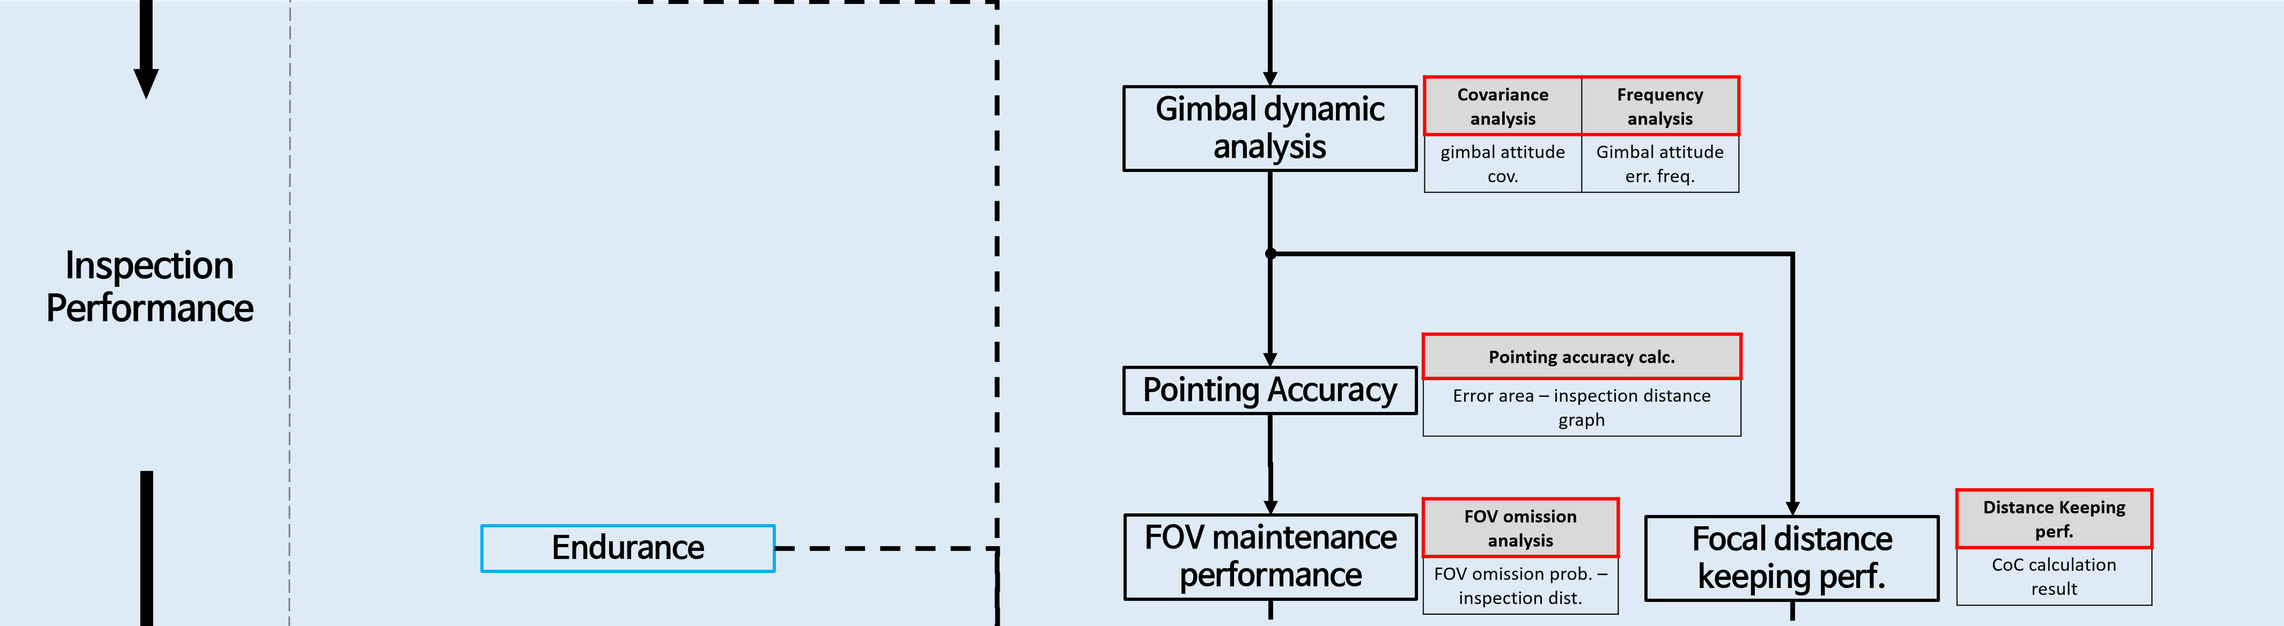

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## **User Input**

**index guide**

1 : roll rate (p)

2 : pitch rate (q)

3 : yaw rate (r)

4 : Roll angle ($\phi$)

5 : Pitch angle ($\theta$)

6 : Yaw angle ($\psi$)

7 : u

8 : v

9 : w

10: X

11: Y

12: Z

13: gimbal Roll

14: gimbal Pitch

15: gimbal Yaw

isGimbalVehicle = includeSweep;
if isGimbalVehicle
    gvResult = load("gvResult.mat");
    gvResult = gvResult.gvResult;
end

다음 사용 중 오류가 발생함: load
파일 'gvResult.mat'을(를) 읽을 수 없습니다. 해당 파일 또는 디렉터리가 없습니다.

covResult = load("covResult.mat")
covResult = covResult.covResult;
sampleVariable = load("sampleVariable.mat")
sampleVariable = sampleVariable.sampleVariable;
inspectionDistance = 10
confidence = 0.9
calcDensity = 100
lensF = 2.8
lensName = "Nikon Z7"
CoCLimit = 0.025

## APPENDIX

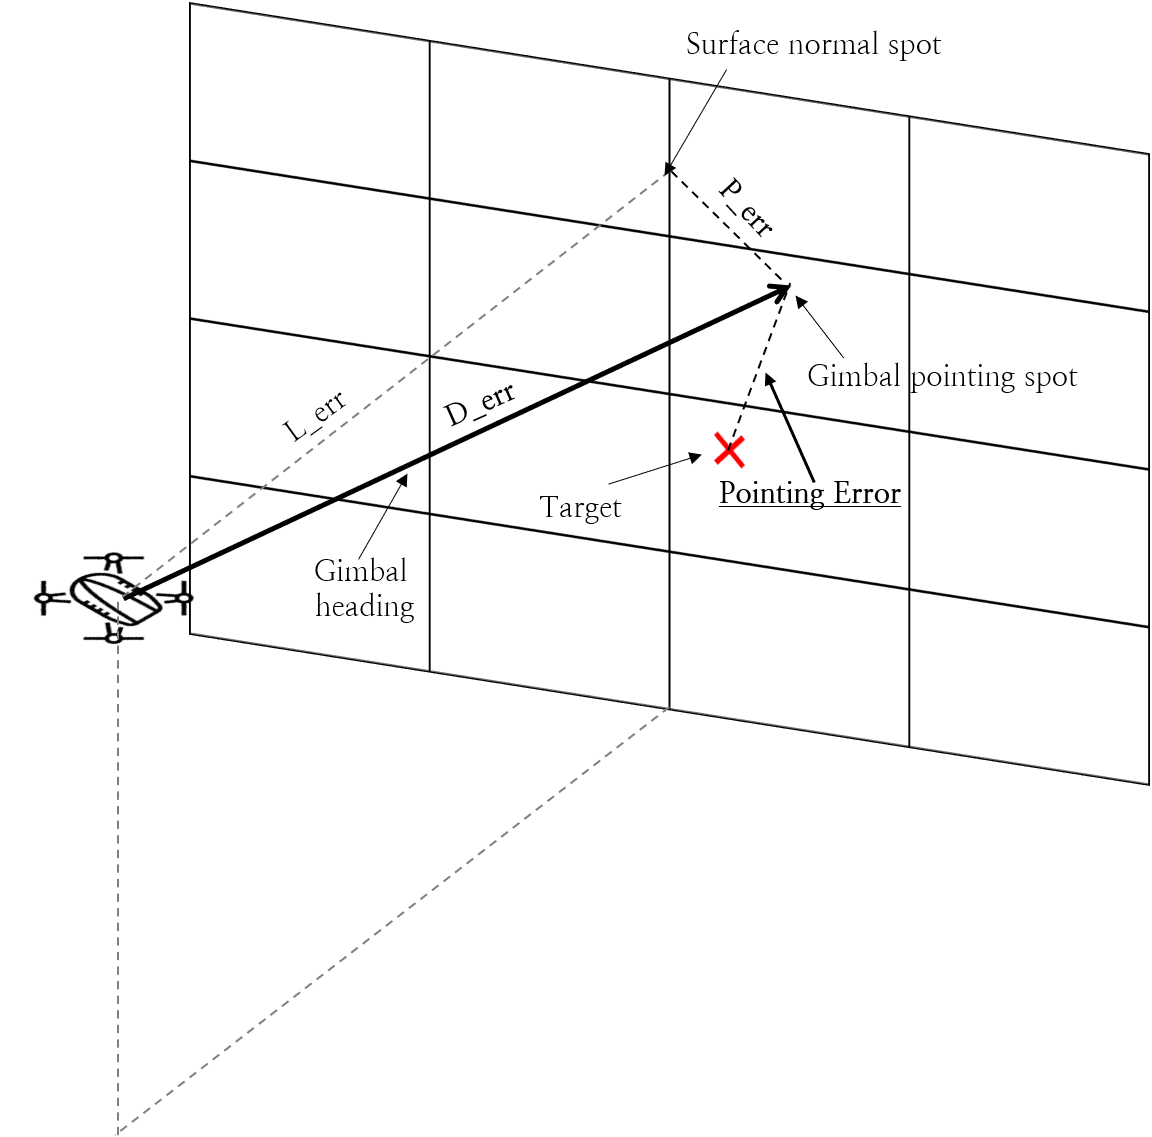

## Gimbal Holding Performance

### Basic dynamic characteristic

#### Step response

#### Frequency response

Bandwidth

GM - PM

### Gimbal - Vehicle interference

This part is overfitted.

dataName = {'Roll - gimbalRoll','Roll - gimbalPitch','Roll - gimbalYaw'};
gvTableResult = [];
figure(1)
set(gcf,'Position',[10 10 800 600])
for i = 1:3
    gvSys = tf(gvResult{i}.Num,gvResult{i}.Den,'ioDelay',gvResult{1}.Delay); 
    subplot(1,3,i)
    margin(gvSys)
    hold on
    grid on
    title(dataName{i},'fontsize',14)
    ylabel('');
    [gpeak, fpeak] = getPeakGain(gvSys);
    gvTableResult(i,:) = [gpeak, fpeak/2/pi];
end
sgtitle('Bode plot')
columns = {'Peak gain [dB]', 'Peak frequency [hz]'};
rows = dataName;
T = table(gvTableResult(:,1),gvTableResult(:,2),'Rownames',rows);
T.Properties.VariableNames = columns

### Gimbal attitude error distribution 

What is this?

Std deviation

columns = {'posHold','velHold'};
rows = {'gimbal Roll [deg]','gimbal Pitch [deg]','gimbal Yaw [deg]'};
T = table(covResult.posHoldStd(13:15)',covResult.velHoldStd(13:15)','Rownames',rows);
T.Properties.VariableNames = columns

Covariance matrix

covResult.pos(13:15,13:15)
covResult.vel(13:15,13:15)

## Pointing Accuracy

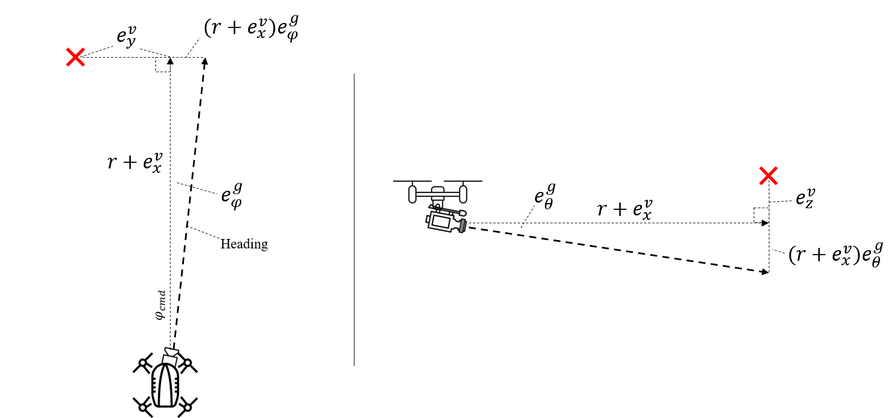


$$l_{err} = (r+e_{x}^v+SSE_x)$$



$$Pointing_{err} = \sqrt{\{l_{err}tan(e_\psi^g+SSE_\psi^g)+e_y^v+SSE_y\}^{2}+\{l_{err}tan(e_\theta^g+SSE_\theta^g)+e_{z}^v+SSE_z\}^{2}}$$


#### Pointing error distribution

% Pointing Accuracy calculation
yawG_err_p = sampleVariable.pos(:,15) * d2r;
pitchG_err_p = sampleVariable.pos(:,14) * d2r;
yawG_sse_p = covResult.posHoldStd(15) * d2r;
pitchG_sse_p = covResult.posHoldStd(14) * d2r;

X_err_p = sampleVariable.pos(:,10);
Y_err_p = sampleVariable.pos(:,10); %%TODO 11
Z_err_p = sampleVariable.pos(:,12);

l_err_p =  inspectionDistance + X_err_p;
Perr_x_p = l_err_p .* tan(yawG_err_p + yawG_sse_p) + Y_err_p;
Perr_y_p = l_err_p .* tan(pitchG_err_p + pitchG_sse_p) + Z_err_p;

yawG_err_v = sampleVariable.vel(:,15) * d2r;
pitchG_err_v = sampleVariable.vel(:,13) * d2r; %%TODO 14
yawG_sse_v = covResult.velHoldStd(15) * d2r;
pitchG_sse_v = covResult.velHoldStd(13) * d2r; %%TODO 14

X_err_v = sampleVariable.vel(:,10);
Y_err_v = sampleVariable.vel(:,10); %%TODO 11
Z_err_v = sampleVariable.vel(:,12);

l_err_v =  inspectionDistance + X_err_v;
Perr_x_v = l_err_v .* tan(yawG_err_v + yawG_sse_v) + Y_err_v;
Perr_y_v = l_err_v .* tan(pitchG_err_v + pitchG_sse_v) + Z_err_v;

% Multivariate Analysis
[pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(Perr_x_p,Perr_y_p,confidence);
[vel_confidence_area,vel_out,vel_maxPdf,vel_peripheral,vel_X,vel_Y] = multiVariateAnalysis(Perr_x_v,Perr_y_v,confidence);
A = [num2str(confidence*100),'% posHold confidence area is ',num2str(pos_confidence_area),' [deg^2]'];
disp(A);
A = [num2str(confidence*100),'% velHold confidence area is ',num2str(vel_confidence_area),' [deg^2]'];
disp(A);
posEdgeIdx = convhull(pos_peripheral);
velEdgeIdx = convhull(vel_peripheral);

figure(2)
clf
hold on
% plot(sampleVariable.pos(:,xIdx)+covResult.posHoldMean(xIdx),sampleVariable.pos(:,yIdx)+covResult.posHoldMean(yIdx),'.')
% plot(sampleVariable.vel(:,xIdx)+covResult.velHoldMean(xIdx),sampleVariable.vel(:,yIdx)+covResult.velHoldMean(yIdx),'m.');
plot(Perr_x_p,Perr_y_p,'.')
plot(Perr_x_v,Perr_y_v,'m.')

contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
contour(vel_X,pos_Y,vel_out/vel_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
grid on
plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
plot(vel_peripheral(:,1),vel_peripheral(:,2),'.g','MarkerSize',10)
plot(pos_peripheral(posEdgeIdx,1),pos_peripheral(posEdgeIdx,2),'y-')
plot(vel_peripheral(velEdgeIdx,1),vel_peripheral(velEdgeIdx,2),'g-')
axis equal
titleText = ['Pointing Accuracy at ', num2str(inspectionDistance), 'm distance'];
title(titleText);
xlabel('X deviation [m]')
ylabel('Y deviation [m]')
set(gcf,'Position',[10 10 700 700])

#### Pointing accuracy - range graph

## Pointing stability


$$l_{err} = (r+e_{x}^v+SSE_x)$$



$$Pointing_{err} = \sqrt{\{l_{err}tan(e_\psi^g+SSE_\psi^g)+e_y^v+SSE_y\}^{2}+\{l_{err}tan(e_\theta^g+SSE_\theta^g)+e_{z}^v+SSE_z\}^{2}}$$


#### Shaking rate distribution

% Shake rate calculation
yawG_err_p = sampleVariable.pos(:,15) * d2r;
pitchG_err_p = sampleVariable.pos(:,14) * d2r;
yawG_sse_p = covResult.posHoldStd(15) * d2r;
pitchG_sse_p = covResult.posHoldStd(14) * d2r;

X_err_p = sampleVariable.pos(:,10);
Y_err_p = sampleVariable.pos(:,10); %%TODO 11
Z_err_p = sampleVariable.pos(:,12);

l_err_p =  inspectionDistance + X_err_p;
Perr_x_p = l_err_p .* tan(yawG_err_p + yawG_sse_p) + Y_err_p;
Perr_y_p = l_err_p .* tan(pitchG_err_p + pitchG_sse_p) + Z_err_p;

yawG_err_v = sampleVariable.vel(:,15) * d2r;
pitchG_err_v = sampleVariable.vel(:,13) * d2r; %%TODO 14
yawG_sse_v = covResult.velHoldStd(15) * d2r;
pitchG_sse_v = covResult.velHoldStd(13) * d2r; %%TODO 14

X_err_v = sampleVariable.vel(:,10);
Y_err_v = sampleVariable.vel(:,10); %%TODO 11
Z_err_v = sampleVariable.vel(:,12);

l_err_v =  inspectionDistance + X_err_v;
Perr_x_v = l_err_v .* tan(yawG_err_v + yawG_sse_v) + Y_err_v;
Perr_y_v = l_err_v .* tan(pitchG_err_v + pitchG_sse_v) + Z_err_v;

% Multivariate Analysis
[pos_confidence_area,pos_out,pos_maxPdf,pos_peripheral,pos_X,pos_Y] = multiVariateAnalysis(Perr_x_p,Perr_y_p,confidence);
[vel_confidence_area,vel_out,vel_maxPdf,vel_peripheral,vel_X,vel_Y] = multiVariateAnalysis(Perr_x_v,Perr_y_v,confidence);
A = [num2str(confidence*100),'% posHold confidence area is ',num2str(pos_confidence_area),' [deg^2]'];
disp(A);
A = [num2str(confidence*100),'% velHold confidence area is ',num2str(vel_confidence_area),' [deg^2]'];
disp(A);
posEdgeIdx = convhull(pos_peripheral);
velEdgeIdx = convhull(vel_peripheral);

figure(3)
clf
hold on
% plot(sampleVariable.pos(:,xIdx)+covResult.posHoldMean(xIdx),sampleVariable.pos(:,yIdx)+covResult.posHoldMean(yIdx),'.')
% plot(sampleVariable.vel(:,xIdx)+covResult.velHoldMean(xIdx),sampleVariable.vel(:,yIdx)+covResult.velHoldMean(yIdx),'m.');
plot(Perr_x_p,Perr_y_p,'.')
plot(Perr_x_v,Perr_y_v,'m.')

contour(pos_X,pos_Y,pos_out/pos_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
contour(vel_X,pos_Y,vel_out/vel_maxPdf,[0.5 0.2 0.1 0.05 0.01],'ShowText','on')
grid on
plot(pos_peripheral(:,1),pos_peripheral(:,2),'.y','MarkerSize',10)
plot(vel_peripheral(:,1),vel_peripheral(:,2),'.g','MarkerSize',10)
plot(pos_peripheral(posEdgeIdx,1),pos_peripheral(posEdgeIdx,2),'y-')
plot(vel_peripheral(velEdgeIdx,1),vel_peripheral(velEdgeIdx,2),'g-')
axis equal
titleText = ['Pointing Accuracy at ', num2str(inspectionDistance), 'm distance'];
title(titleText);
xlabel('X deviation [m]')
ylabel('Y deviation [m]')
set(gcf,'Position',[10 10 700 700])

#### Shaking rate - range graph

## Focal Point Maintenance Performance

#### Focal point maintenance performance

% Inspection distance calc.
yawG_err_p = sampleVariable.pos(:,15) * d2r;
pitchG_err_p = sampleVariable.pos(:,14) * d2r;
yawG_sse_p = covResult.posHoldStd(15) * d2r;
pitchG_sse_p = covResult.posHoldStd(14) * d2r;

X_err_p = sampleVariable.pos(:,10);
Y_err_p = sampleVariable.pos(:,10); %%TODO 11
Z_err_p = sampleVariable.pos(:,12);

l_err_p =  inspectionDistance + X_err_p;
Perr_x_p = l_err_p .* tan(yawG_err_p + yawG_sse_p) + Y_err_p;
Perr_y_p = l_err_p .* tan(pitchG_err_p + pitchG_sse_p) + Z_err_p;
Perr_tot_p = sqrt(Perr_x_p.^2 + Perr_y_p.^2);
Derr_p = sqrt(Perr_tot_p.^2 + l_err_p.^2);

CoC_p = abs(Derr_p - inspectionDistance)./Derr_p .* lensF^2 ./ 3.5 ./ (inspectionDistance - lensF);

yawG_err_v = sampleVariable.vel(:,15) * d2r;
pitchG_err_v = sampleVariable.vel(:,13) * d2r; %%TODO 14
yawG_sse_v = covResult.velHoldStd(15) * d2r;
pitchG_sse_v = covResult.velHoldStd(13) * d2r; %%TODO 14

X_err_v = sampleVariable.vel(:,10);
Y_err_v = sampleVariable.vel(:,10); %%TODO 11
Z_err_v = sampleVariable.vel(:,12);

l_err_v =  inspectionDistance + X_err_v;
Perr_x_v = l_err_v .* tan(yawG_err_v + yawG_sse_v) + Y_err_v;
Perr_y_v = l_err_v .* tan(pitchG_err_v + pitchG_sse_v) + Z_err_v;
Perr_tot_v = sqrt(Perr_x_v.^2 + Perr_y_v.^2);
Derr_v = sqrt(Perr_tot_v.^2 + l_err_v.^2);

CoC_v = abs(Derr_v - inspectionDistance)./Derr_v .* lensF^2 ./ 3.5 ./ (inspectionDistance - lensF);

% CoC probability distribution
figure(4)
h1 = histogram(CoC_p);
hold on
h2 = histogram(CoC_v);
h1.Normalization = 'probability';
h1.BinWidth = 0.25;
h2.Normalization = 'probability';
h2.BinWidth = 0.25;

plot([CoCLimit CoCLimit],[0 0.5],'k--')

#### CoC satisfaction probability - range graph

## FOV Omission Probability

#### FOV omission probability - range graph

## Function definition

function [confidence_area,out,maxPdf,peripheral,X,Y] = multiVariateAnalysis(x_data,y_data,confidence)
% Internal parameters : DO NOT TOUCH
global calcDensity
level = 1-confidence;
zRange = 5;
cumulated = 0;
index = [];
peripheral = [];
density = calcDensity;

% calculate maxpdf
mu_x = mean(x_data);
mu_y = mean(y_data);
std_x = std(x_data);
std_y = std(y_data);
covar = cov([x_data,y_data]);

maxPdf = mvnpdf([mu_x mu_y],[mu_x mu_y],covar);
thres = level * maxPdf;

% distribution data for plotting
[X,Y] = meshgrid(linspace(mu_x-std_x*zRange,mu_x+std_x*zRange,50),linspace(mu_y-std_y*zRange,mu_y+std_y*zRange,50));
out = BiNorm(X,Y,[mu_x;mu_y],covar);

% distribution data for prob. calc.
xGrid = linspace(mu_x-zRange*std_x,mu_x+zRange*std_x,density);
yGrid = linspace(mu_y-zRange*std_y,mu_y+zRange*std_y,density);
xGrid(end) = [];
yGrid(end) = [];
xGridSize = xGrid(2)-xGrid(1);
yGridSize = yGrid(2)-yGrid(1);
gridArea = xGridSize * yGridSize;

for i = xGrid
    for j = yGrid
        if mvnpdf([i j],[mu_x mu_y],covar) >= thres
            cumulated = cumulated + mvncdf([i j],[i+xGridSize j+yGridSize],[mu_x mu_y],covar);
            index = vertcat(index,[i,j]);
        end
    end
end

% cumulated % for verification. This value must be equal to 'confidence' param.

for i = 1:length(index)
    if boxed(i,index,xGridSize,yGridSize)
        peripheral = vertcat(peripheral,index(i,:));
    end
end

confidence_area = length(index) * gridArea;
end

function flag = boxed(n,index,xGridSize,yGridSize)
x = index(n,1); y = index(n,2);
right = 0; left = 0; up = 0; down = 0;
flag = 0;

if isempty(find(abs(index(:,1)-(x+xGridSize)) < xGridSize/2 & abs(index(:,2)-y) < yGridSize/2,1))
    right = 1;
end
if isempty(find(abs(index(:,1)-(x-xGridSize)) < xGridSize/2 & abs(index(:,2)-y) < yGridSize/2,1))
    left = 1;
end
if isempty(find(abs(index(:,1)-x) < xGridSize/2 & abs(index(:,2)-(y+yGridSize)) < yGridSize/2,1))
    up = 1;
end
if isempty(find(abs(index(:,1)-x) < xGridSize/2 & abs(index(:,2)-(y-yGridSize)) < yGridSize/2,1))
    down = 1;
end

if up || down || right || left
    flag = 1;
end

end